clc;
clear all;
close all;

% 2
[Im,map] = imread('corn.tif');

if ~isempty(map)
    I = ind2rgb(Im,map);
end
whos I

  Name        Size                 Bytes  Class     Attributes

  I         415x312x3            3107520  double              



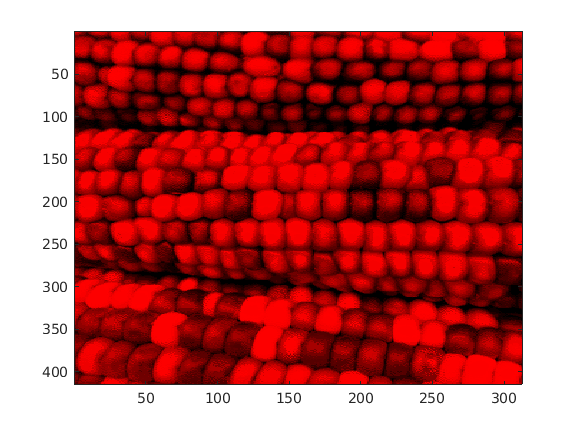

% 2.1 
I_R = I(:,:,1);  
I_G = I(:,:,2);
I_B = I(:,:,3); 

zero = zeros(size(I, 1), size(I, 2));
redI = cat(3, I_R, zero, zero);
greenI = cat(3, zero, I_G, zero);
blueI = cat(3, zero, zero, I_B);
K = cat(3, I_R, I_G, I_B);

N=255;
s1= 0:1/(N-1):1;
mapR=zeros(N,3);
mapR(:,1,:)=s1;
mapG=zeros(N,3);
mapG(:,2,:)=s1;
mapB=zeros(N,3);
mapB(:,3,:)=s1;

figure
imagesc(I_R)
colormap(mapR)

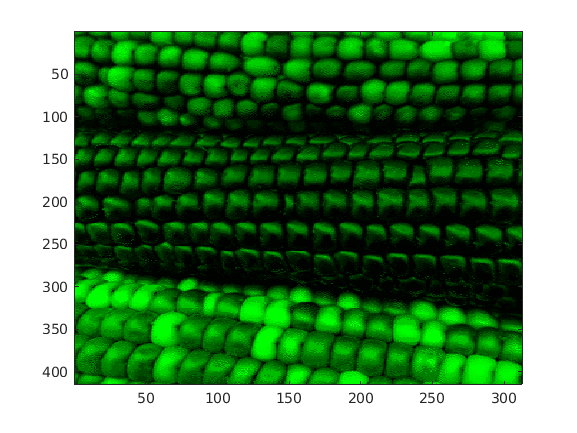

figure
imagesc(I_G)
colormap(mapG)

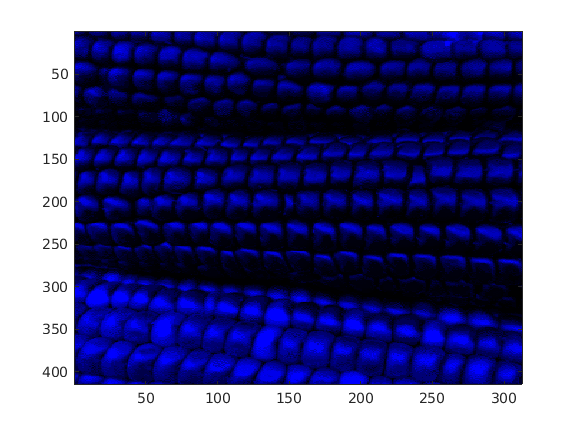

figure
imagesc(I_B)
colormap(mapB)

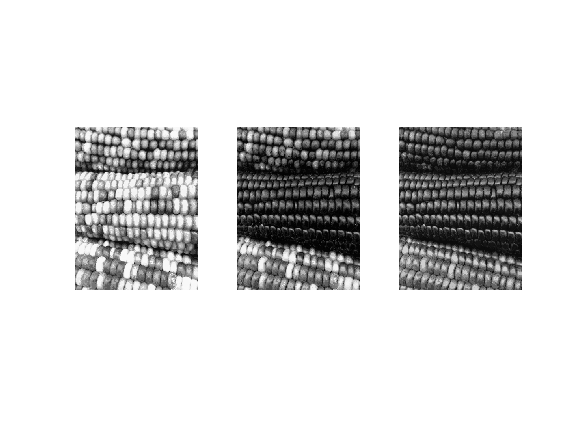

figure 
subplot(1,3,1);
imshow(I_R)
subplot(1,3,2);
imshow(I_G)
subplot(1,3,3);
imshow(I_B)

N=255;
newmap1=map(1:256/N:256,:,:);

imagen1=ind2rgb(Im,newmap1);

N=254;
newmap2=map(1:256/N:256,:,:);

imagen2=ind2rgb(Im,newmap2);

N=253;
newmap3=map(1:256/N:256,:,:);

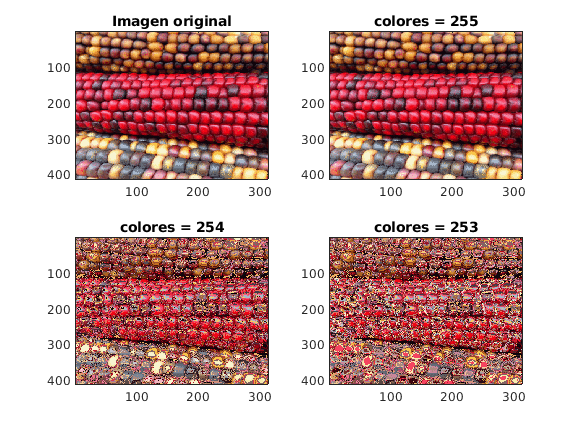

imagen3=ind2rgb(Im,newmap3);

figure
subplot(2,2,1); 
image(I)
title('Imagen original')
subplot(2,2,2); 
imagesc(imagen1)
title('colores = 255')
subplot(2,2,3);
imagesc(imagen2)
title('colores = 254')
subplot(2,2,4);
imagesc(imagen3)
title('colores = 253')

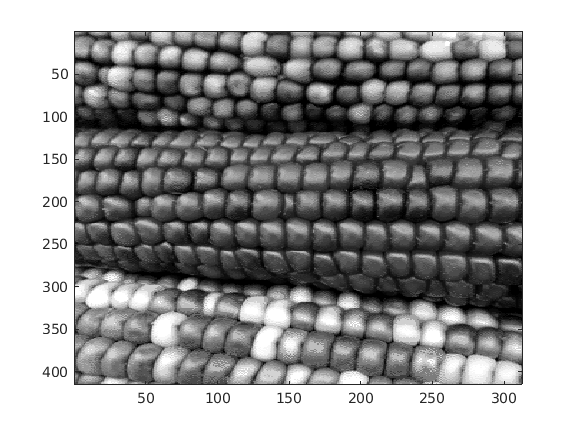

Gr=rgb2gray(I);
subplot(1,1,1); 
imagesc(Gr)
colormap(gray)

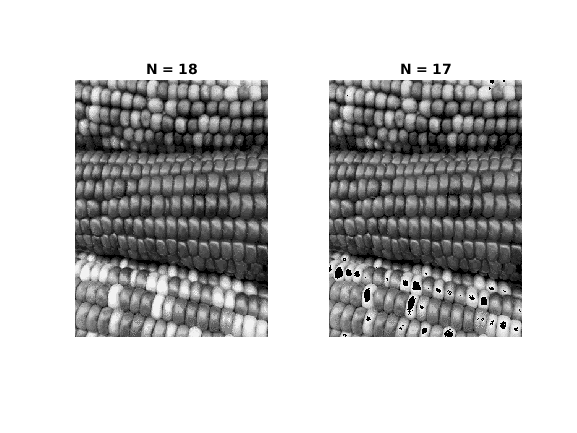

Gr=rgb2gray(I);
Gr1=Gr;

N=18;
N=N+1;
Gr(Gr<=1/N)=N;
p=1/N;
for r=1:N-1 
    Gr(Gr<=p)=N+r;
    p=p+(1/N);
end
Gr=(Gr-N)/N;
figure
subplot(1,2,1);
imshow(Gr)
title('N = 18')

N=17;
N=N+1;
Gr1(Gr1<=1/N)=N;
p=1/N;
for r=1:N-1 
    Gr1(Gr1<=p)=N+r;
    p=p+(1/N);
end
Gr1=(Gr1-N)/N;
subplot(1,2,2);
imshow(Gr1)
title('N = 17')

whos Gr

  Name        Size               Bytes  Class     Attributes

  Gr        415x312            1035840  double              



whos Gr1

  Name        Size               Bytes  Class     Attributes

  Gr1       415x312            1035840  double              

